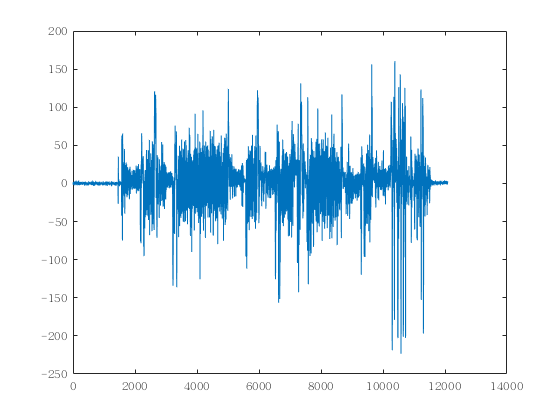

clear all
data=textread('AHRS/data/imudata01.txt');
time=data(:,1);
dT=diff(time);
dT=[dT(1);dT];
data = data(:,2:end);
%角速度去零飘处理
staticNum=300;static=299;
wx=(data(1:end,1)-mean(data(staticNum-static:staticNum,1)))*180.0/pi;
wy=(data(1:end,2)-mean(data(staticNum-static:staticNum,2)))*180.0/pi;
wz=(data(1:end,3)-mean(data(staticNum-static:staticNum,3)))*180.0/pi;
plot(wz)

%加速度计归一化处理
axRaw=data(1:end,4);
ayRaw=data(1:end,5);
azRaw=data(1:end,6);

位置 2 处的索引超出数组边界(不能超出 5)。

normAcc=sqrt(sum(data(1:end,4:6).^2,2));
ax=axRaw./normAcc;
ay=ayRaw./normAcc;
az=azRaw./normAcc;

%%积分量初始化
initEuler=[atan2d(-ay(1),-az(1)) asind(ax(1)) zeros(length(ax(1)),1)];%欧拉角初始化
initQuaternion=euler2quat_self(initEuler);%四元数初始化
quaternion=initQuaternion;
quaternionMahony=initQuaternion;

n=length(wx);%数据长度
GyroAngle=zeros(n,3);%纯陀螺仪算出的角度
MahonyAngle=zeros(n,3);%融合加速度计后算出的角度
q0=zeros(n,1);q1=zeros(n,1);q2=zeros(n,1);q3=zeros(n,1);%mahony滤波器中间变量值
exInt=zeros(n,1);eyInt=zeros(n,1);ezInt=zeros(n,1);%mahony滤波器中间变量值
obj=struct('Accelerometer',zeros(3),'Quaternion',initQuaternion,'Gyroscope',zeros(3),'eInt',zeros(3),'Kp',-1,'Ki',0);

%陀螺仪积分过程
for i=1:n
    %纯陀螺仪角速度积分
    quaternion=quatInt(quaternion,[wx(i);wy(i);wz(i)],dT(i));
    GyroAngle(i,1:3)=quat2euler_self(quaternion);
end
%纯加速度计算出的角度
AccAngle=[atan2d(-ay,-az) asind(ax) zeros(length(ax),1)];
%积分过程
for i=1:n
    Accelerometer = [ax(i) ay(i) az(i)];
    Gyroscope = [ax(i) ay(i) az(i)];
    SamplePeriod = dT(i);
    obj = UpdateIMU(obj, Gyroscope, Accelerometer,SamplePeriod);
%     MahonyAngle(i,1:3)=quat2euler_self(obj.Quaternion);
    MahonyAngle(i,1:3) = quatern2euler(quaternConj(obj.Quaternion)) * (180/pi);
end


%画图
figure
subplot(311);
plot(GyroAngle(:,1));hold on;
plot(AccAngle(:,1));hold on;
plot(MahonyAngle(:,1));
title('横滚角曲线图')
legend('gyro','acc','mahony');
subplot(312);
plot(GyroAngle(:,2));hold on;
plot(AccAngle(:,2));hold on;
plot(MahonyAngle(:,2));
title('俯仰角曲线图')
legend('gyro','acc','mahony');
subplot(313);
plot(GyroAngle(:,3));hold on;
plot(MahonyAngle(:,3));
title('航向角曲线图')
legend('gyro','mahony');


function obj = UpdateIMU(obj, Gyroscope, Accelerometer,SamplePeriod)
    q = obj.Quaternion; % short name local variable for readability
 
    % Normalise accelerometer measurement
    if(norm(Accelerometer) == 0), return; end   % handle NaN
    Accelerometer = Accelerometer / norm(Accelerometer);	% normalise magnitude
 
    % Estimated direction of gravity and magnetic flux
    v = [2*(q(2)*q(4) - q(1)*q(3))
        2*(q(1)*q(2) + q(3)*q(4))
        q(1)^2 - q(2)^2 - q(3)^2 + q(4)^2];
 
    % Error is sum of cross product between estimated direction and measured direction of field
    e = cross(Accelerometer, v); 
    if(obj.Ki > 0)
        obj.eInt = obj.eInt + e * SamplePeriod;   
    else
        obj.eInt = [0 0 0];
    end
            
    % Apply feedback terms
    Gyroscope = Gyroscope + obj.Kp * e + obj.Ki * obj.eInt;            
            
    % Compute rate of change of quaternion
    qDot = 0.5 * quaternProd(q, [0 Gyroscope(1) Gyroscope(2) Gyroscope(3)]);
 
    % Integrate to yield quaternion
    q = q + qDot * SamplePeriod;
    obj.Quaternion = q / norm(q); % normalise quaternion
end
